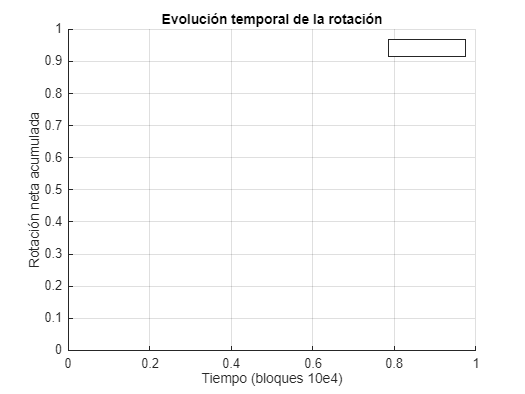

k_values = [1, 2, 5];
colores = lines(length(k_values));
block_size = 10000;
num_simulaciones = 5;  % Número de simulaciones para promediar

%% Parámetros del sistema comunes
m = 1;
eta = 1;
T1 = 1;
T2 = 2;
x1_0 = 0;
x2_0 = 0;
tspan = [0, 100000];
dt = 0.01;
N = round((tspan(2)-tspan(1))/dt);
t = linspace(tspan(1), tspan(2), N);
kb = 1;
x1_eq = 0;
x2_eq = 0;
sqrt_term1 = 1;
sqrt_term2 = 2;

figure; hold on; grid on;

for idx_k = 1:length(k_values)
    k = k_values(idx_k);

    % Mallado adaptado a cada k
    if k == 1
        step_size = 0.4; x_min = -3.2; x_max = 3.2; y_min = -4; y_max = 4;
    elseif k == 2
        step_size = 0.225; x_min = -1.8; x_max = 1.8; y_min = -2.25;   y_max = 2.25;
    elseif k == 5
        step_size = 0.15; x_min = -1.20; x_max = 1.20;y_min = -1.5;   y_max = 1.5;
    end

    x_vals = x_min:step_size:x_max;
    y_vals = y_min:step_size:y_max;
    nx = length(x_vals);
    ny = length(y_vals);
    [Xg, Yg] = meshgrid(x_vals, y_vals);
    xx1 = reshape(Xg, [], 1);
    yy1 = reshape(Yg, [], 1);

    num_blocks = floor(N / block_size);
    rotaciones_sim = zeros(num_simulaciones, num_blocks);

    for sim = 1:num_simulaciones
        % Simulación individual
        x1 = zeros(1, N);
        x2 = zeros(1, N);
        x1(1) = x1_0;
        x2(1) = x2_0;
        for n = 1:N-1
            dW1 = sqrt(dt)*randn;
            dW2 = sqrt(dt)*randn;
            x1(n+1) = x1(n) + ((-2*k*(x1(n)-x1_eq) + k*(x2(n)-x2_eq))/eta)*dt + (sqrt_term1/eta)*dW1;
            x2(n+1) = x2(n) + ((-2*k*(x2(n)-x2_eq) + k*(x1(n)-x1_eq))/eta)*dt + (sqrt_term2/eta)*dW2;
        end

        for b = 1:num_blocks
            idx_start = 1;
            idx_end = b * block_size;

            x1_block = x1(idx_start:idx_end);
            x2_block = x2(idx_start:idx_end);
            xy2 = [x1_block(:), x2_block(:)];
            ixy = round(xy2/step_size)*step_size;

            trans1 = ixy(1:end-1, :);  
            trans2 = ixy(2:end, :);   
            transvec = trans1 - trans2;
            sal = [trans1, transvec];
            ent = [trans2, transvec];
            allpts = [sal; ent];

            tol = 1e-6;
            flow = zeros(length(xx1), 4);
            for kk = 1:length(xx1)
                indx = find(abs(allpts(:,1) - xx1(kk)) < tol);
                indy = find(abs(allpts(:,2) - yy1(kk)) < tol);
                ind = intersect(indx, indy);
                if isempty(ind)
                    sdx = 0; sdy = 0;
                else
                    sdx = sum(allpts(ind,3));   
                    sdy = sum(allpts(ind,4));   
                end
                flow(kk,:) = [xx1(kk), yy1(kk), sdx, sdy];
            end

            flowX = flow(:,3);
            flowY = flow(:,4);
            UX = flowX;
            UY = flowY;

            UXgrid = reshape(UX, ny, nx); 
            UYgrid = reshape(UY, ny, nx);
            [curlz, ~] = curl(Xg, Yg, UXgrid, UYgrid);

            rotaciones_sim(sim, b) = sum(curlz(:), 'omitnan');
        end
    end

    % Media de las rotaciones por bloque
    rotacion_media = mean(abs(rotaciones_sim), 1);
    plot(1:num_blocks, (abs(rotacion_media)), '.-', ...
         'Color', colores(idx_k,:), 'DisplayName', ['k = ' num2str(k)]);
end

xlabel('Tiempo (bloques 10e4)');
ylabel('Rotación neta acumulada');
title('Evolución temporal de la rotación');
legend;